% datatable81 = unnamed;

Import data table and convert to array

%load datatable.mat
prepdata = EAint;

data(:,1) = (prepdata(:,1)-1)./(2-1);
data(:,2) = (prepdata(:,2)-120)./(160-120);
data(:,3) = (prepdata(:,3)-300)./(500-300);
data(:,4) = (prepdata(:,4)-2)./(5-2);
data(:,5) = (prepdata(:,5)-min(prepdata(:,5)))./(max(prepdata(:,5))-min(prepdata(:,5)));

% 
% pn = [p1n p2n p3n p4n]';
% tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

## hyperparameter optimization (number of neurons)

%load datatable.mat
%data = datatable81;

numdata = numel(data(:,1))

numdata = 81

foldsize = ceil(numdata/5);

%% randomize
randata = data(randperm(size(data,1)),:)

randata =     0.5000         0    0.5000    0.5000    0.3527
    1.0000         0    0.5000    0.5000    0.4748
    1.0000    1.0000    1.0000    1.0000    0.6757
    0.5000         0         0    1.0000    0.5968
         0         0         0         0    0.0091
         0    0.5000    0.5000         0    0.0316
    0.5000    0.5000    1.0000         0    0.0634
         0    1.0000    0.5000         0    0.0585
         0    0.5000    1.0000    0.5000    0.4198
         0         0         0    0.5000    0.4110


%% normalize
normdata = normalize(randata,"range");

fold1 = normdata(1:foldsize,:);
fold2 = normdata(foldsize+1:2*foldsize,:);
fold3 = normdata(2*foldsize+1:3*foldsize,:);
fold4 = normdata(3*foldsize+1:4*foldsize,:);
fold5 = normdata(4*foldsize+1:numdata,:);

f1 = [fold1;fold2;fold3;fold4;fold5]';
f2 = [fold2;fold1;fold3;fold4;fold5]';
f3 = [fold3;fold1;fold2;fold4;fold5]';
f4 = [fold4;fold1;fold2;fold3;fold5]';
f5 = [fold5;fold1;fold2;fold3;fold4]';

valInd = 1:foldsize;
trainInd = foldsize+1:numdata;

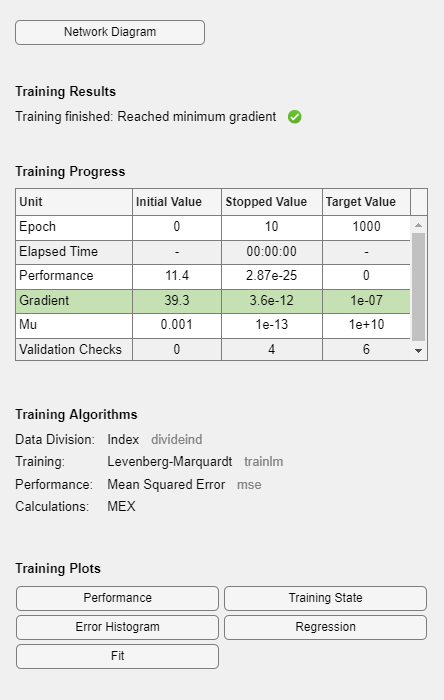

for i=1:50
Fcn = 'poslin';
netf1 = fitnet(i,'trainlm');
netf2 = fitnet(i,'trainlm');
netf3 = fitnet(i,'trainlm');
netf4 = fitnet(i,'trainlm');
netf5 = fitnet(i,'trainlm');

netf1.divideFcn = 'divideind';
netf1.divideParam.valInd = 1:foldsize;
netf1.divideParam.trainInd = foldsize+1:numdata;
netf1.inputs{1}.processFcns   = {'removeconstantrows'};
netf1.outputs{2}.processFcns  = {'removeconstantrows'};
netf1.layers{1}.transferFcn = Fcn;

netf2.divideFcn = 'divideind';
netf2.divideParam.valInd = 1:foldsize;
netf2.divideParam.trainInd = foldsize+1:numdata;
netf2.inputs{1}.processFcns   = {'removeconstantrows'};
netf2.outputs{2}.processFcns  = {'removeconstantrows'};
netf2.layers{1}.transferFcn = Fcn;

netf3.divideFcn = 'divideind';
netf3.divideParam.valInd = 1:foldsize;
netf3.divideParam.trainInd = foldsize+1:numdata;
netf3.inputs{1}.processFcns   = {'removeconstantrows'};
netf3.outputs{2}.processFcns  = {'removeconstantrows'};
netf3.layers{1}.transferFcn = Fcn;

netf4.divideFcn = 'divideind';
netf4.divideParam.valInd = 1:foldsize;
netf4.divideParam.trainInd = foldsize+1:numdata;
netf4.inputs{1}.processFcns   = {'removeconstantrows'};
netf4.outputs{2}.processFcns  = {'removeconstantrows'};
netf4.layers{1}.transferFcn = Fcn;

netf5.divideFcn = 'divideind';
netf5.divideParam.valInd = 1:foldsize;
netf5.divideParam.trainInd = foldsize+1:numdata;
netf5.inputs{1}.processFcns   = {'removeconstantrows'};
netf5.outputs{2}.processFcns  = {'removeconstantrows'};
netf5.layers{1}.transferFcn = Fcn;

[netf1,trf1] = train(netf1,f1(1:4,:),f1(5,:));
[netf2,trf2] = train(netf2,f2(1:4,:),f2(5,:));
[netf3,trf3] = train(netf3,f3(1:4,:),f3(5,:));
[netf4,trf4] = train(netf4,f4(1:4,:),f4(5,:));
[netf5,trf5] = train(netf5,f5(1:4,:),f5(5,:));
err(i) =(trf1.best_vperf+trf2.best_vperf+trf3.best_vperf+trf4.best_vperf+trf5.best_vperf)/5;
end


plot(err);
[M0,I0] = min(err);
disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    21



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0023



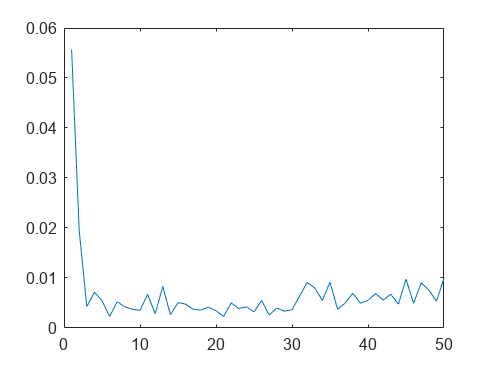

hold off;

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

Unrecognized function or variable 'pn'.


plot(mse_val0,'-');

disp('training index of best MSE value set is')
disp(I0)
disp('Which has MSE =')
disp(M0)
hold off;

net1 = fitnet(20,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-6;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 20
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

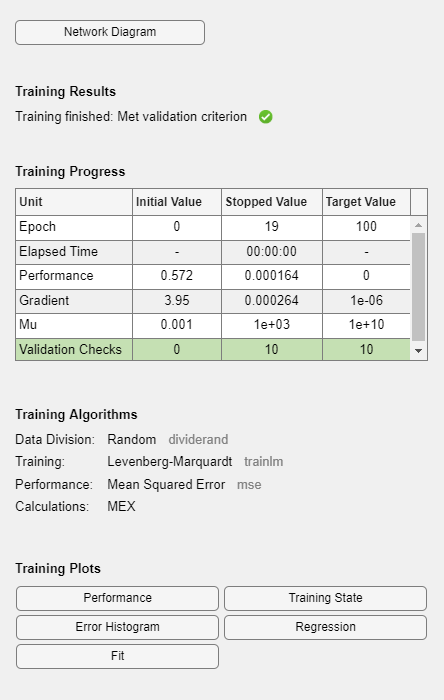

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

%input = normalize(datatable144(:,1:4),'range');
[net1,tr1] = train(net1,f1(1:4,:),f1(5,:));


output_ANN1 = net1(data(:,1:4)')

output_ANN1 =     0.0034    0.4353    0.8080   -0.0062    0.3181    0.7552    0.0225    0.3272    0.7307    0.0594    0.6265    0.9171    0.0405    0.4803    0.8754    0.0844    0.4315    0.9024    0.0875    0.7883    1.0020    0.1160    0.5423    0.9082    0.1626    0.4787    0.9331   -0.0098    0.4405    0.5946    0.0239    0.3557    0.6363    0.0147    0.3218    0.6535    0.0186    0.5895    0.6978    0.0178    0.5167    0.7152    0.0189    0.4325    0.7288    0.0580    0.7705    0.7807    0.0712    0.6478


ANNMASS = ((output_ANN1(1,:))*(max(prepdata(:,5))-min(prepdata(:,5))))+min(prepdata(:,5))

ANNMASS = 1.0e+03 *

    1.6949    5.1924    8.2101    1.6171    4.2431    7.7826    1.8501    4.3167    7.5841    2.1482    6.7401    9.0933    1.9955    5.5567    8.7556    2.3514    5.1613    8.9740    2.3757    8.0500    9.7804    2.6067    6.0582    9.0210    2.9841    5.5433    9.2230    1.5887    5.2346    6.4818    1.8611    4.5475    6.8198    1.7867    4.2734    6.9585    1.8182    6.4406    7.3178    1.8116    5.8514    7.4584    1.8205    5.1696    7.5686    2.1374    7.9062    7.9888    2.2444    6.9126


%ANNSEA = ((output_ANN1(1,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))
FEA = (data(:,5)).*(max(prepdata(:,5))-min(prepdata(:,5)))+min(prepdata(:,5))

FEA = 1.0e+03 *

    1.7415
    4.9957
    8.2097
    1.7453
    4.7604
    7.7079
    1.8650
    4.3002
    7.7352
    2.0887


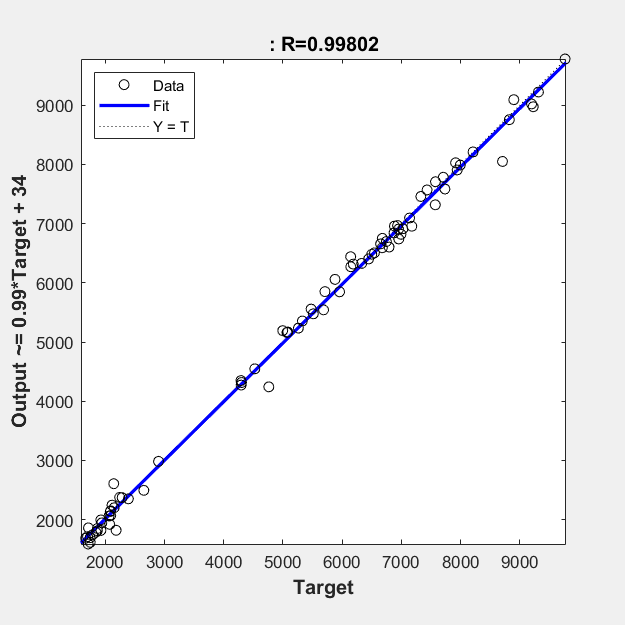

plotregression(FEA,ANNMASS);

%plotregression(datatable144(:,6),ANNSEA');
% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));

input(:,1) = (datatest(:,1)-1)./(2-1);

Reference to a cleared variable datatest.

input(:,2) = (datatest(:,2)-120)./(160-120);
input(:,3) = (datatest(:,3)-300)./(500-300);
input(:,4) = (datatest(:,4)-2)./(5-2);
input(:,5) = (datatest(:,5)-min(datatest(:,5)))./(max(datatest(:,5))-min(datatest(:,5)));

output_ANN = net1(input(:,1:4)')
ans=((output_ANN').*(max(datatest(:,5))-min(datatest(:,5))))+min(datatest(:,5));
plotregression(datatest(:,5),ans');

pred = net1([0.75 0.75 0.75 0.75]')

pred = 0.5457


IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 105.9218

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

maxipf=max(data(:,5))
minipf=min(data(:,5))
maxsea=max(data(:,6))
minsea=min(data(:,6))

## ANN function test unit

data = datatable144;
testing(:,1) = (testingdata(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
testing(:,2) = (testingdata(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
testing(:,3) = (testingdata(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
testing(:,4) = (testingdata(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));

x = testing;
%x = normalize(data(:,1:4),"range");
output_ANN1 = net1(x');
ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   131.5616  120.1267  127.1037   99.4583   87.3852   78.3497   81.1701   92.0331   84.0244   73.9588


%ANNSEA = ((output_ANN1(1,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

plotregression(testing(:,5),ANNIPF');
plotregression(testing(:,6),ANNSEA');

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.

Y = poslin144(R);